# Computing $\tilde \alpha_1$ and $\tilde \alpha_2$

We have the nonautonomous equation 

$\dot u = B(x) u, \quad u: \mathbb R \to \mathbb R^4$,

where $B$ is formed by linearizing the Swift-Hohenberg equation about the steady state solution $\varphi$ and using a symplectic change of coordinates to form the first order, four dimensional system. 

Define $\lim_{x \to \pm \infty} B(x) = B_\infty$ and suppose that the eigenvalues and eigenvectors of $B_\infty$ are given by $\mu^{s/u}_{1,2}$ and$V^{s/u}_{1,2}$ where 

- $\mu_1^s = \overline \mu_2^s$, $\mu_1^u = \overline \mu_2^u$

- 
$$\mu_1^s = - \mu_1^u$$


Recall that we express  $E^u_-(x) = \text{span} \{U_\varphi(x), U_1(x)\}$ with $U_\varphi
$ the derivative of the pulse solution and $U_1(x)$ limits to one of the unstable eigendirections of the asymptotic coefficient matrix, $B_\infty$ (after factoring out the expontential growth).

We want to express $U_\varphi$ as the following linear combination 


$$\begin{array}{rcl}
U_\varphi (x) &=&  \sum_{i = 1}^j \tilde \alpha_j e^{-\mu_jx} \big(V^s_j + \tilde W_j^{+,s}(x) \big) \\
&=&  \sum_{i = 1}^j \tilde \alpha_j e^{-\mu_jx} W_j^{+,s}(x)  \\
\end{array}$$


 where $W^{+,s}_j(x) = V^s_j  + \tilde W^{+,s}_j(x)$ and $\| \tilde W^{+,s}_j \| \to 0$ as $x \to \infty$. 

Our goal is to compute numerical approximations for $U_\varphi$ and $W^{+,s}_j$ on $[-L,L]$ for fixed $L$ and evaluate them at $x = 0$ to obtain $\tilde\alpha_j$. 

FIx $L$. We can compute a numerical approximation of $U_\varphi$ on $[-L,L]$ by integrating the derivative of the pulse at $x=-L$ forward under the nonautonomous flow $\dot u = B(x) u$. The function $W^{+,s}_j$ satisfies the ODE 

$\dot W^{+,s}_j = [B(x) - \mu_j^s] W^{+,s}_j = [B_\infty - \mu_j^s]W^{+,s}_j + \tilde B(x)W^{+,s}_j$                (eq 4.10 in paper)

Similarly, we can compute numerical approximations of $W^{+,s}_j$ by integrating $V_j^s$ backwards from $L$ under the flow generated by the above equation. Define these numerical approximations on the interval $[-L,L]$ as $\bar U_\varphi(x)$ and $\bar W^{+,s}_j(x)$

We can then approximate $\tilde\alpha_j$ by solving the system of $4$ equations:

$U_\varphi(0) = \pmatrix{| & | \cr \bar W^{+,s}_1(0) &  \bar W^{+,s}_2(0) \cr | & |  } \pmatrix{\tilde \alpha_1 \cr \tilde\alpha_2 } $.


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1       0.0882328                           459               1
     1          2      0.00177027       0.452275            143               1
     2          3     0.000400908       0.338144            2.3            1.13
     3          4     9.11572e-06       0.140264           8.11            1.13
     4          5     5.59227e-09      0.0185436          0.265            1.13
     5          6     1.31738e-15    0.000447843       1.45e-05            1.13
     6          7     1.46332e-24    2.24371e-07        1.5e-08            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function toleran

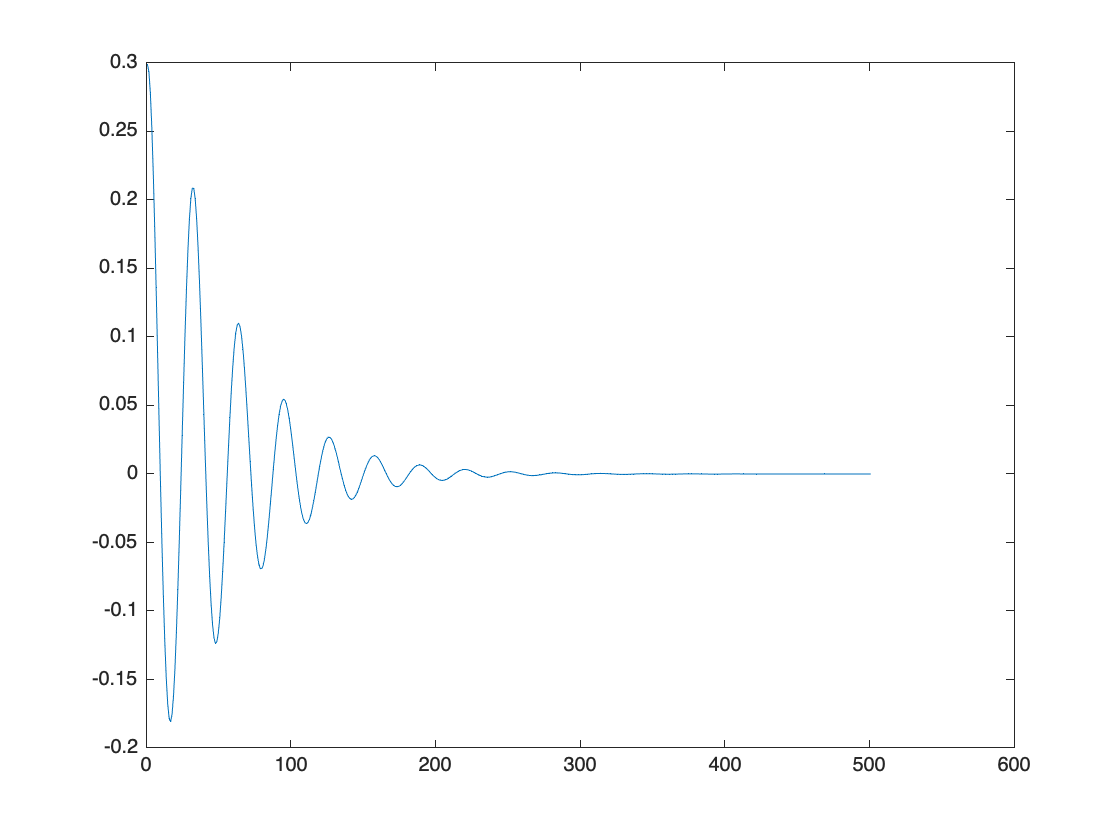

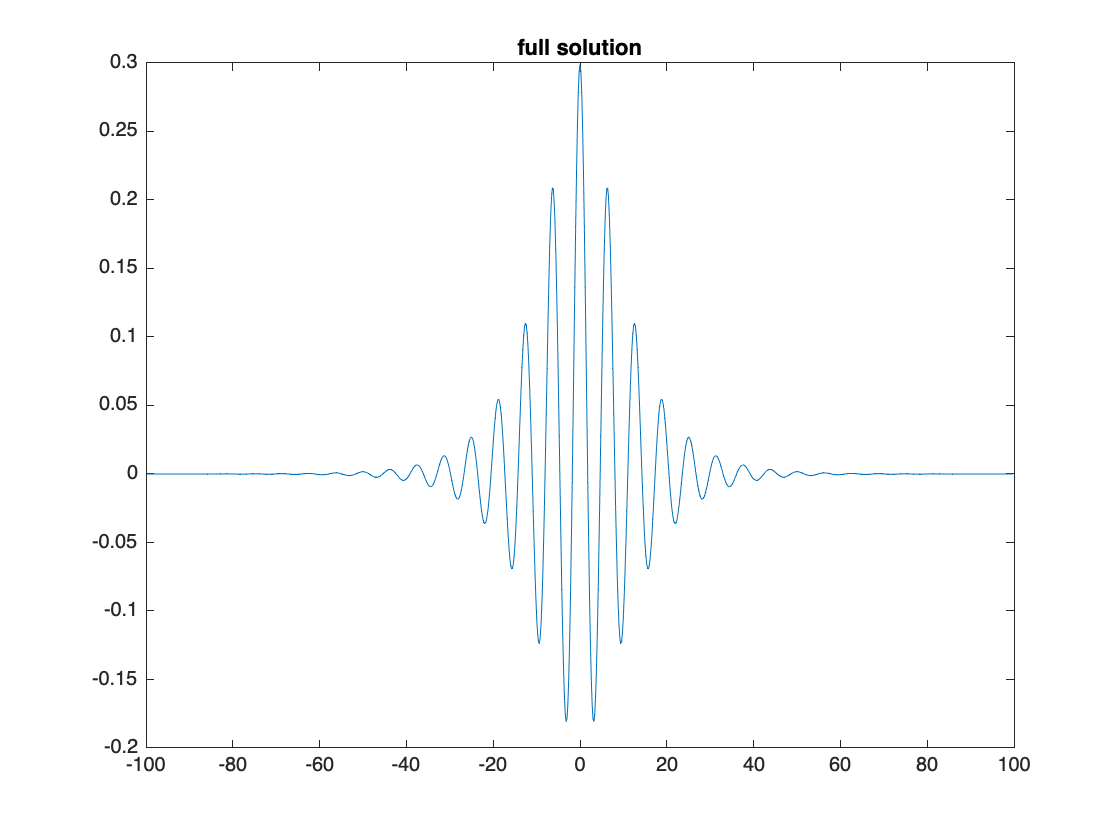

tolerance met
Error:
   1.0174e-11
    0.1209


S =   PulseSolution with properties:

       fourier: [1×1 struct]
      vfParams: [1×1 struct]
          time: 99.8000
    normalForm: [1×1 struct]

clear

vfParams.nu = 1.6;
vfParams.mu = .05;
vfParams.lambda = 0; 

fourier.M = 1000; 
fourier.tol = 1e-14; 
fourier.order = 150; 
 
time = 100; 

normalForm.branch = 0; 
S = PulseSolution(fourier, vfParams, normalForm, time);
S = S.mainPulse()

conjPts.L = 50; 
C = ConjugatePoints(conjPts, vfParams); 
C.Euminus.normalize = 1;

[S,C] = C.mainConjPts(S);
[vectors, values] = C.getBinfEigs()

vectors = struct with fields:
    s: [4×2 double]
    u: [4×2 double]

values = struct with fields:
    s: [-0.1111 + 1.0062i -0.1111 - 1.0062i]
    u: [0.1111 + 1.0062i 0.1111 - 1.0062i]

C.Euminus.normalize = 0;  

W1_ic = [C.Euminus.pulse_ic'; vectors.s(:,1)];
W2_ic = [C.Euminus.pulse_ic'; vectors.s(:,2)];

The stable eigenvectors of $B_\infty$ are given via 

disp(vectors.s) 

  -0.0539 + 0.4879i  -0.0539 - 0.4879i
   0.1630 - 0.4758i   0.1630 + 0.4758i
  -0.5091 + 0.0000i  -0.5091 + 0.0000i
  -0.4849 - 0.1084i  -0.4849 + 0.1084i


C.Esplus.normalize = 0;
[phisol, W1] = integrateStableBasisVecs(C, W1_ic, values.s(1), C.conjPts.L, 0);
[phisol, W2] = integrateStableBasisVecs(C, W2_ic, values.s(2), C.conjPts.L, 0);

By integrating these backwards from $L$= 50, we obtain the following functions

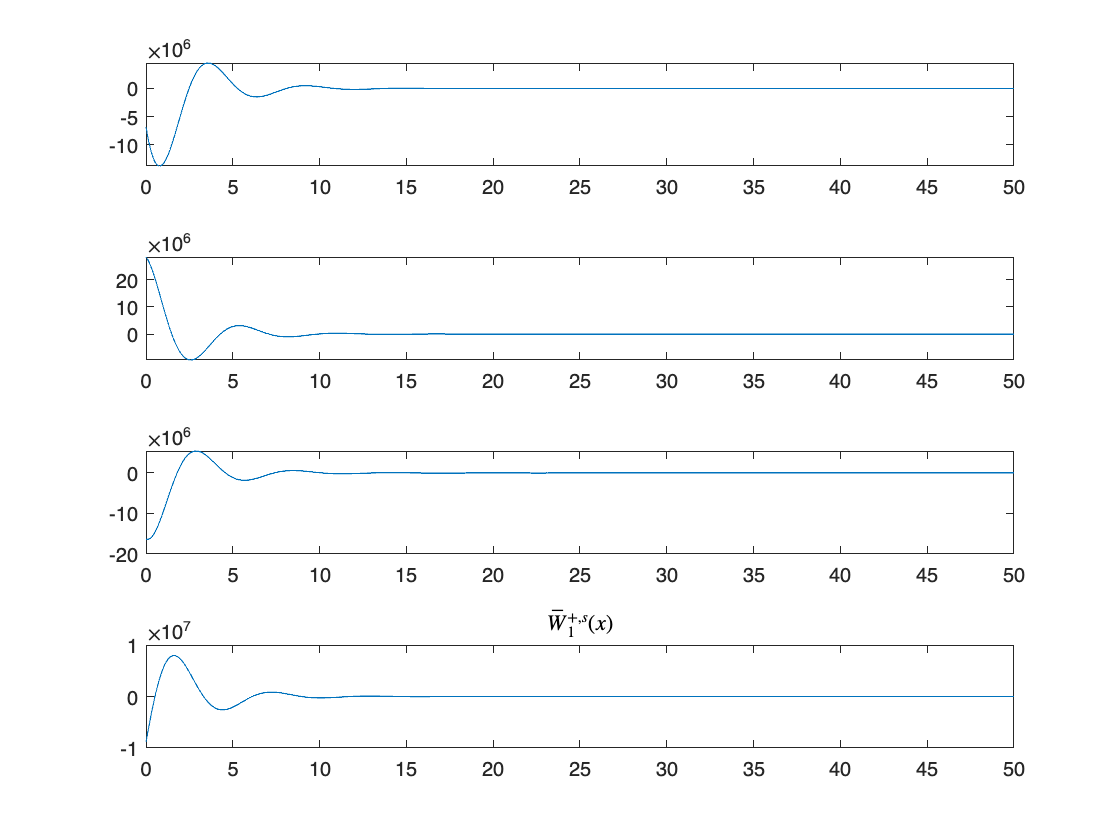

figure 
tiledlayout(4,1)
for i = 1:4
    nexttile 
    plot(W1(:,1), real(W1(:, i+1)))
end 
title('$\bar W^{+,s}_1(x)$', Interpreter = 'latex')

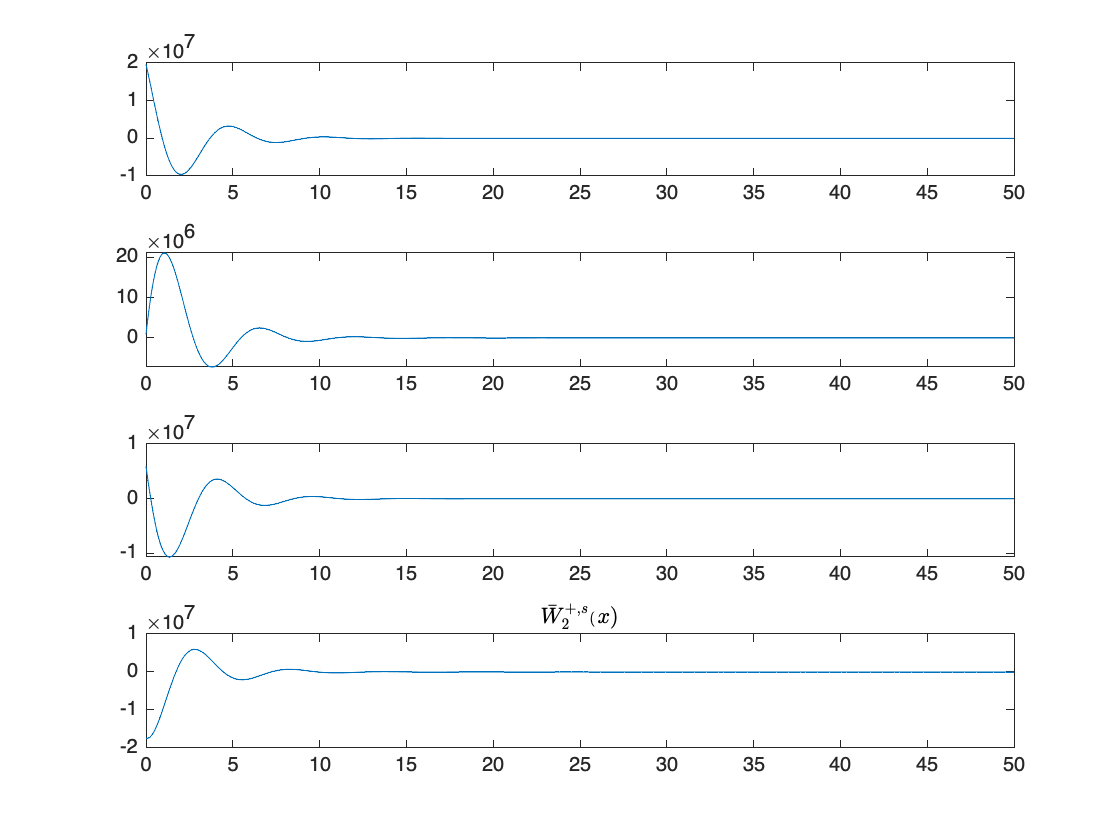


figure
tiledlayout(4,1)
for i = 1:4 
    nexttile 
    plot(W2(:, 1), imag(W2(:, i + 1)))
end
title('$\bar W^{+,s}_2(x)$', Interpreter = 'latex')

phip_time = C.Euminus.timeVec; 
phip = reshape(C.Euminus.frame(:, 2,:), [4, max(size(phip_time))]);

time_norm = abs(phip_time);
ind_0 = find(time_norm == min(time_norm));

The value of $U_\varphi(0)$ is given by 

phip_0 = phip(:, ind_0)

phip_0 =    -0.0000
    0.0000
   -0.6003
   -0.7998


The matrix $\pmatrix{| & | \cr \bar W^{+,s}_1(0) & \bar W^{+,s}_2(0) \cr | & |  }$ is given by: 

mat = [ W1(end, 2:5)',W2(end, 2:5)']

mat = 1.0e+07 *

  -0.6809 + 1.9673i  -0.6809 - 1.9673i
   2.8289 + 0.0931i   2.8289 - 0.0931i
  -1.6252 + 0.5947i  -1.6252 - 0.5947i
  -0.8864 - 1.7386i  -0.8864 + 1.7386i


Solving the system of linear equations gives us: 

ans = linsolve(mat, phip_0)

ans = 1.0e-08 *

   0.7404 - 0.7634i
   0.7404 + 0.7634i


It makes sense for $\tilde \alpha_1$ and $\tilde \alpha_2$ to be complex conjugates because $U_\varphi$ is real valued. 

Now we repeat this computation for a variety of $L$ values. 

candidates = 25:4:60

candidates =     25    29    33    37    41    45    49    53    57


normalize = 0;
alphas_n = zeros(size(candidates, 2), 2);
for i = 1:size(candidates, 2)
    this_a = getAlpha(S, candidates(i), vfParams, normalize)';
    alphas_n(i,:) = this_a;
end

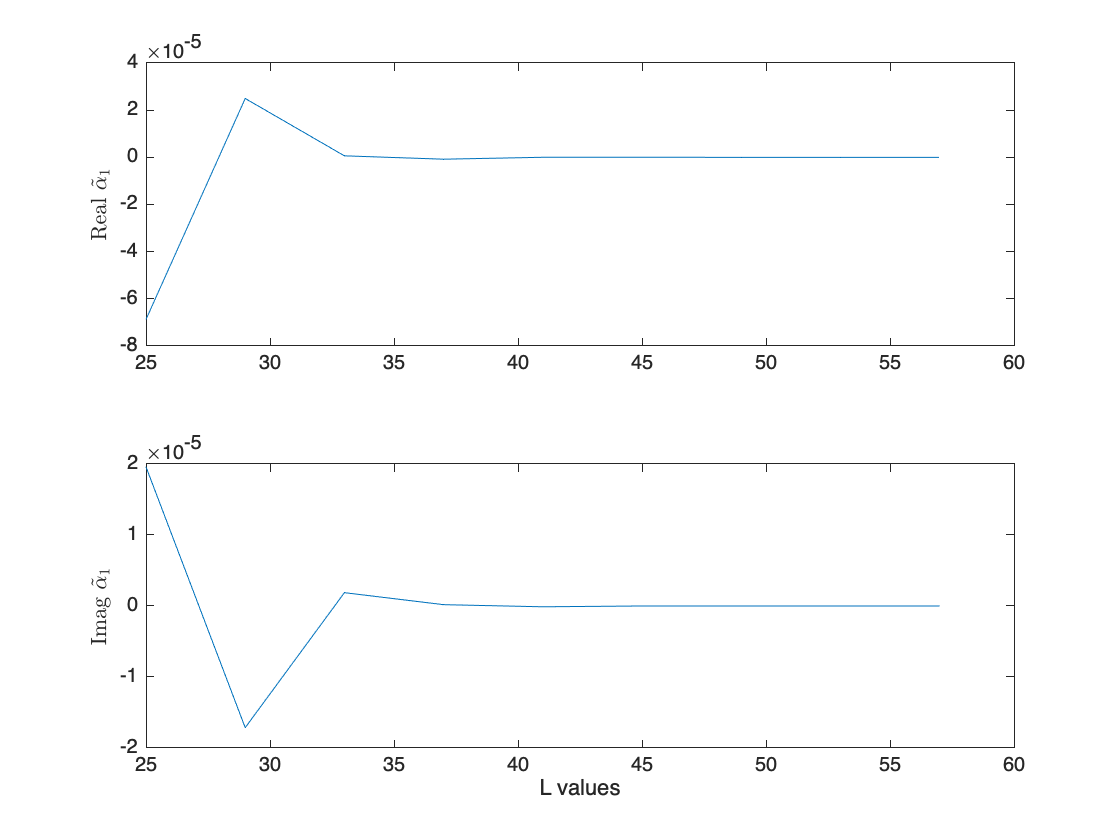

figure 
tiledlayout(2,1)
nexttile
plot(candidates, real(alphas_n(:,1)))
ylabel('Real $\tilde\alpha_1$', Interpreter = 'latex')
nexttile
plot(candidates, imag(alphas_n(:,1)))
ylabel('Imag $\tilde\alpha_1$', Interpreter = 'latex')
xlabel('L values')

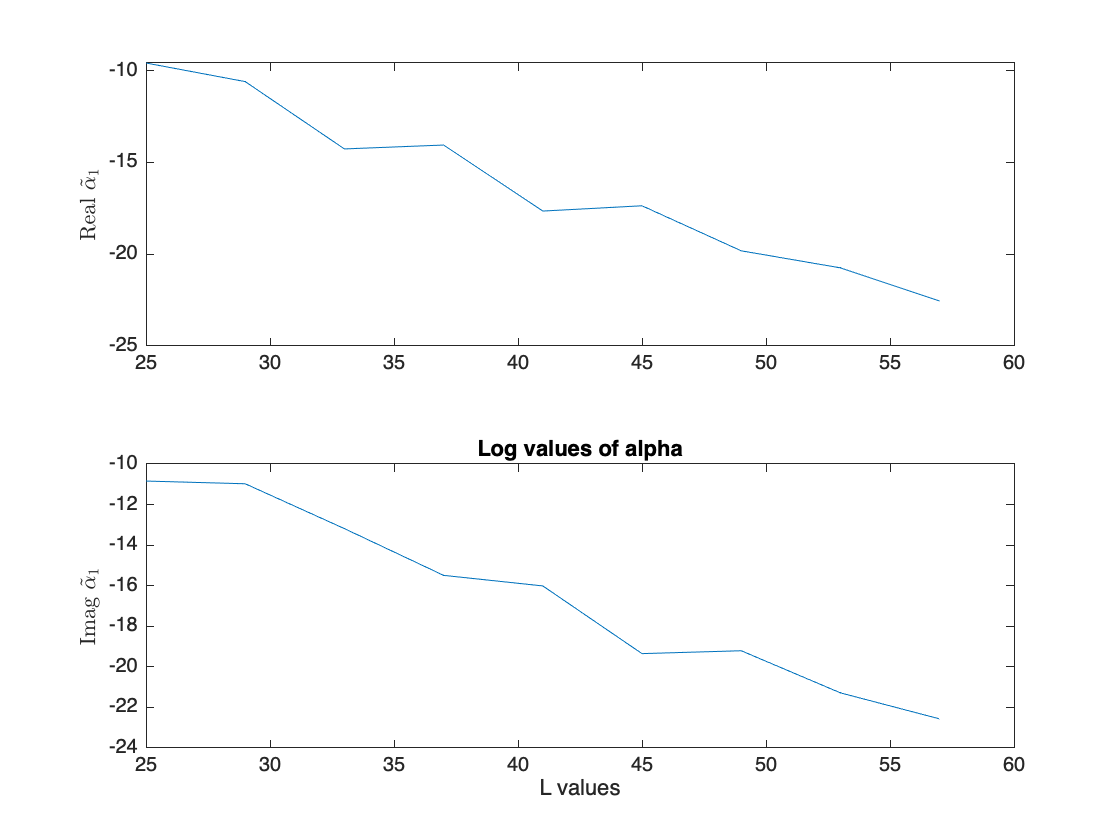

figure 
tiledlayout(2,1)
nexttile
plot(candidates, log(abs(real(alphas_n(:,1)))))
ylabel('Real $\tilde\alpha_1$', Interpreter = 'latex')
nexttile
plot(candidates, log(abs(imag(alphas_n(:,1)))))
ylabel('Imag $\tilde\alpha_1$', Interpreter = 'latex')
xlabel('L values')
title('Log values of alpha')

#### Normalizing $\bar W^{+,s}_j$

The solutions $\bar W_{j}^{+,s}$ are growing exponentially. Now, we normalize them. Define $A(x; \mu) = B(x) - \mu$ and define $\bar y = \frac{W^{+,s}_j}{\|W^{+,s}_j\|}$ . Then we have 


$$\begin{array}{rcl}
\frac{d}{dx}\bar y &=& \frac{d}{dx} \frac{y}{(\langle y, y \rangle)^{1/2}} \\
&=&\dot y \|y\|^{-1} - y\|y\|^{-3}\langle\dot y, y\rangle \\
&=&A(x)y \|y\|^{-1} - y\|y\|^{-3}\langle A(x)y, y\rangle \\
&=&A(x)\bar y- \bar y\langle A(x)\bar y, \bar y\rangle 
\end{array}$$


We repeat the above computation but using the normalized solutions $\bar W^{+,s}_j$. As an example, with $L = 50$, we have 

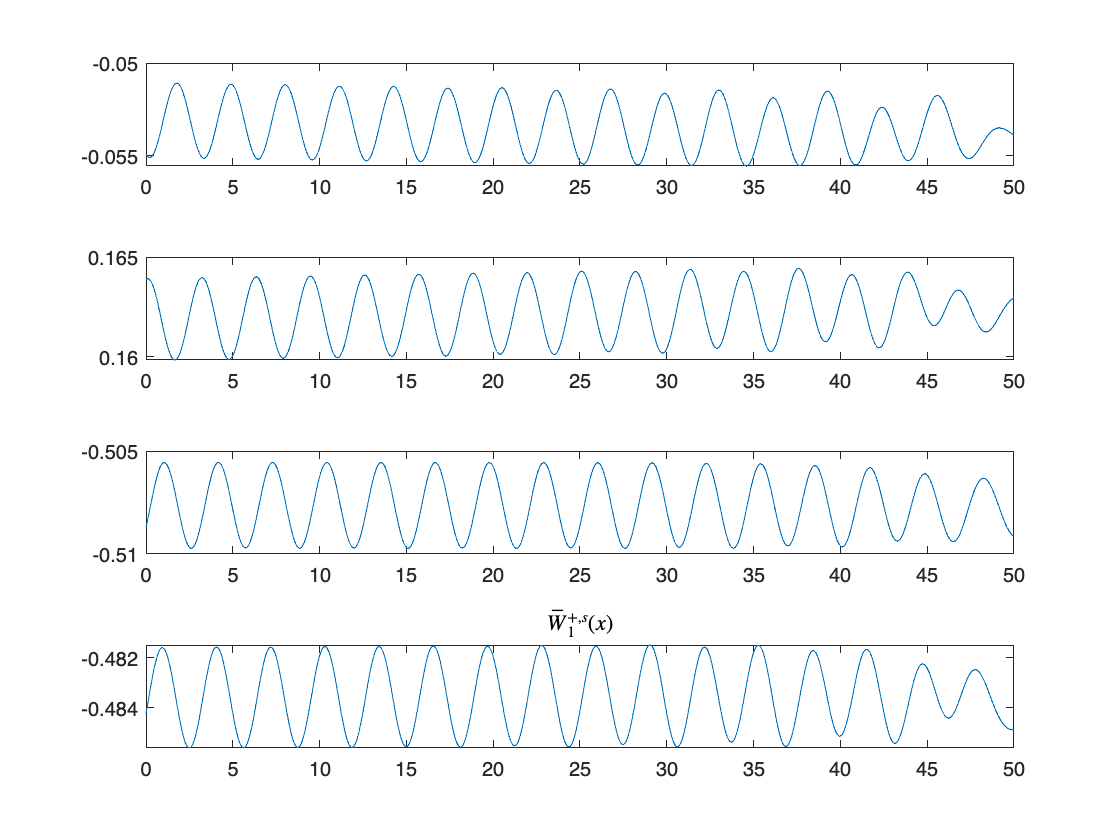

C.Esplus.normalize = 1;
[phisol, W1] = integrateStableBasisVecs(C, W1_ic, values.s(1), C.conjPts.L, 0);
[phisol, W2] = integrateStableBasisVecs(C, W2_ic, values.s(2), C.conjPts.L, 0);

figure 
tiledlayout(4,1)
for i = 1:4
    nexttile 
    plot(W1(:,1), real(W1(:, i+1)))
end 
title('$\bar W^{+,s}_1(x)$', Interpreter = 'latex')

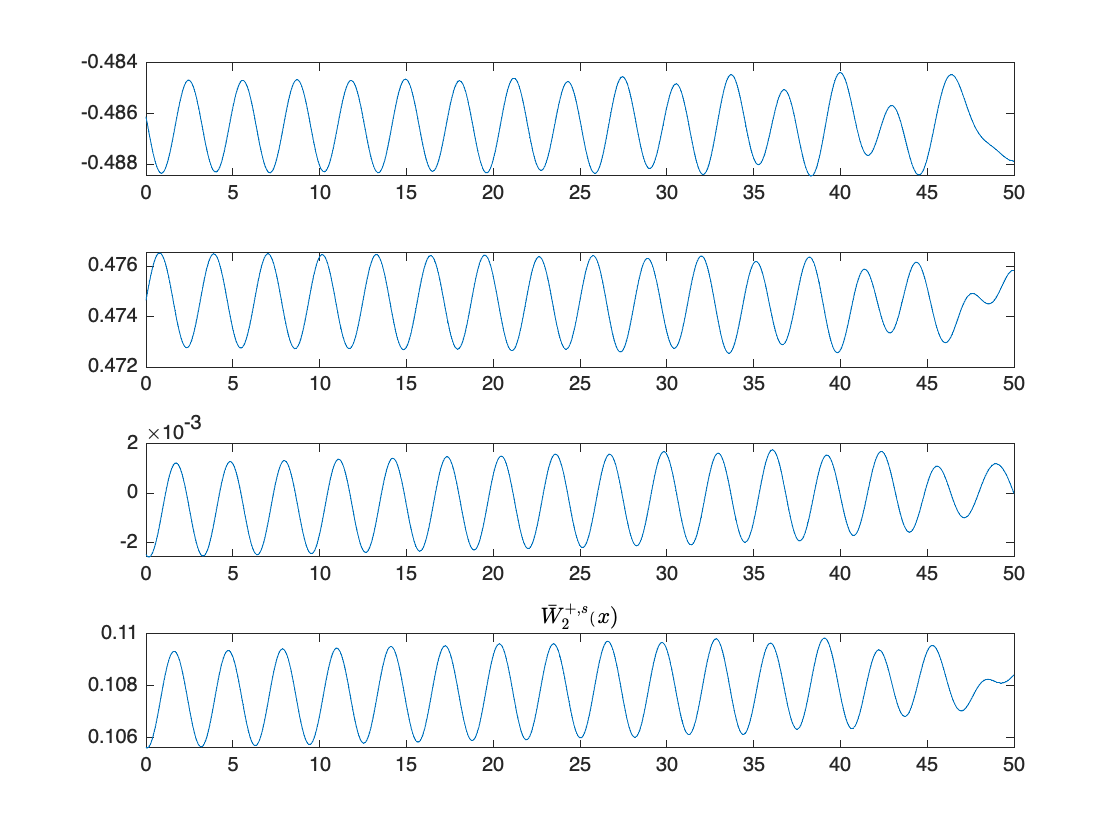


figure
tiledlayout(4,1)
for i = 1:4 
    nexttile 
    plot(W2(:, 1), imag(W2(:, i + 1)))
end
title('$\bar W^{+,s}_2(x)$', Interpreter = 'latex')

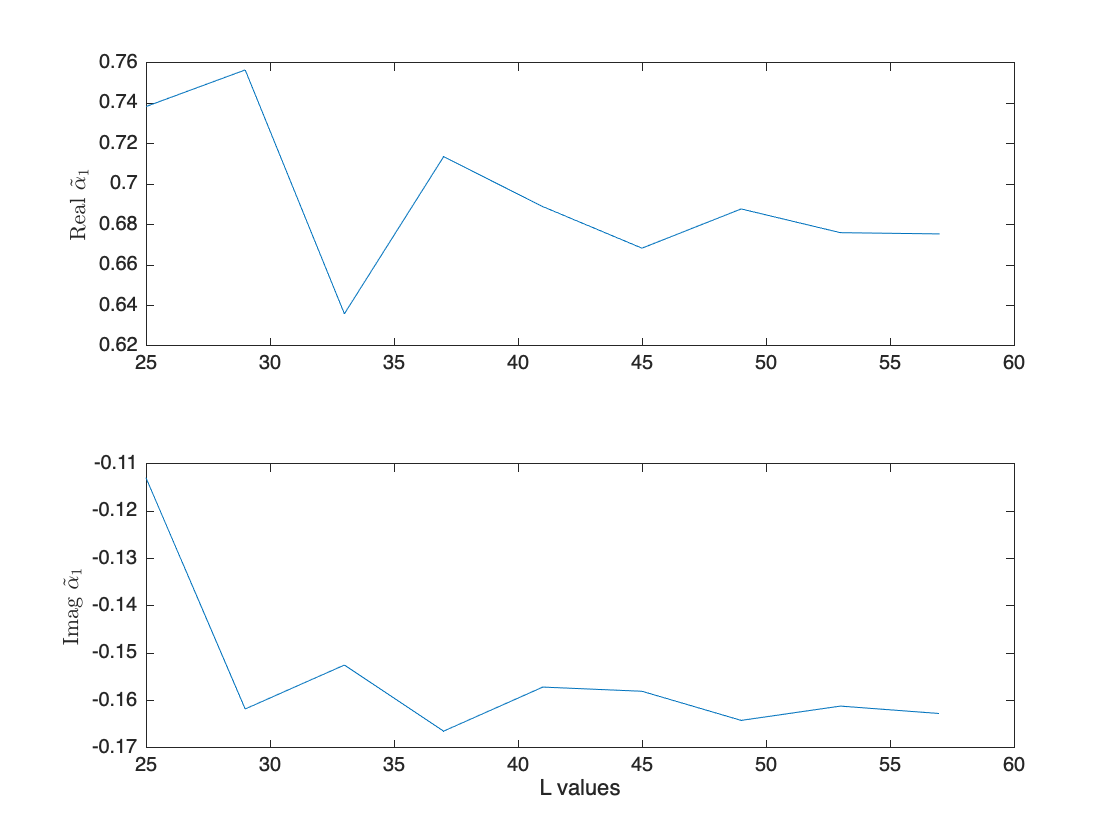



normalize = 1;
alphas = zeros(size(candidates, 2), 2);
for i = 1:size(candidates, 2)
    this_a = getAlpha(S, candidates(i), vfParams, normalize)';
    alphas(i,:) = this_a;
end

figure 
tiledlayout(2,1)
nexttile
plot(candidates, real(alphas(:,1)))
ylabel('Real $\tilde\alpha_1$', Interpreter = 'latex')
nexttile
plot(candidates, imag(alphas(:,1)))
ylabel('Imag $\tilde\alpha_1$', Interpreter = 'latex')
xlabel('L values')

function ans = getAlpha(S, L, vfParams, normalize)
    conjPts.L = L; 
    C = ConjugatePoints(conjPts, vfParams); 
    C.Euminus.normalize = normalize;
    C.Esplus.normalize = normalize; 
    
    [S,C] = C.mainConjPts(S);
    [vectors, values] = C.getBinfEigs();

    W1_ic = [C.Euminus.pulse_ic'; vectors.s(:,1)];
    W2_ic = [C.Euminus.pulse_ic'; vectors.s(:,2)];
    
    [phisol, W1] = C.integrateStableBasisVecs(W1_ic, values.s(1), C.conjPts.L, 0);
    [phisol, W2] = C.integrateStableBasisVecs(W2_ic, values.s(2), C.conjPts.L, 0);

    phip_time = C.Euminus.timeVec; 
    phip = reshape(C.Euminus.frame(:, 2,:), [4, max(size(phip_time))]);
    
    time_norm = abs(phip_time);
    ind_0 = find(time_norm == min(time_norm));
    
    phip_0 = phip(:, ind_0);
    
    mat = [W1(end, 2:5)', W2(end, 2:5)'];
    ans = linsolve(mat, phip_0);

end
